%Johnny Vastola Math 131
clc
clear

a=-5;b=5;n=100;
grid=linspace(a,b,n);
xf=grid(1:end-1);
xb=grid(2:end);
xc=grid(2:end-1);
h=(b-a)/(n-1);


1.

A

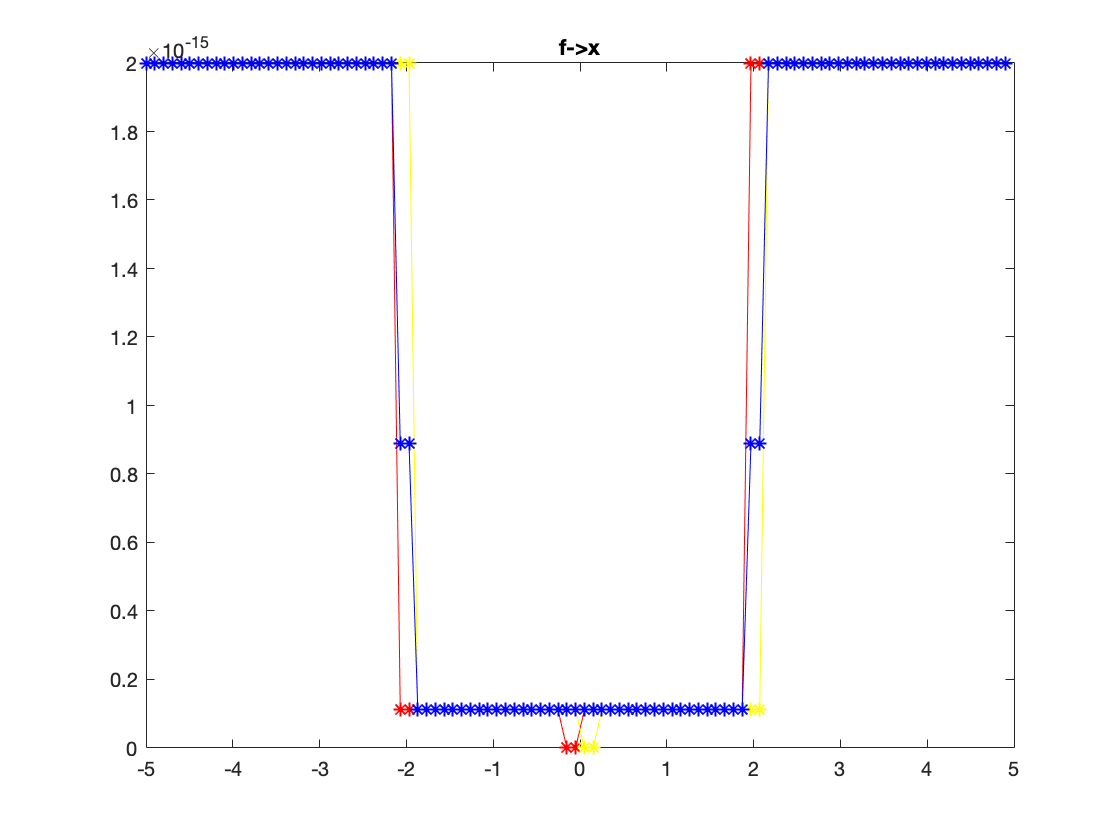

f = @(x) x;
fprime= @(x) 1;
errorf=abs(fprime(xf)-forward(f,xf,h));
errorb=abs(fprime(xf)-backward(f,xf,h));
errorc=abs(fprime(xf)-centered(f,xf,h));
plot(xf,errorf,'*r-',xf,errorb,'*y-',xf,errorc,'*b-')
title('f->x')

B

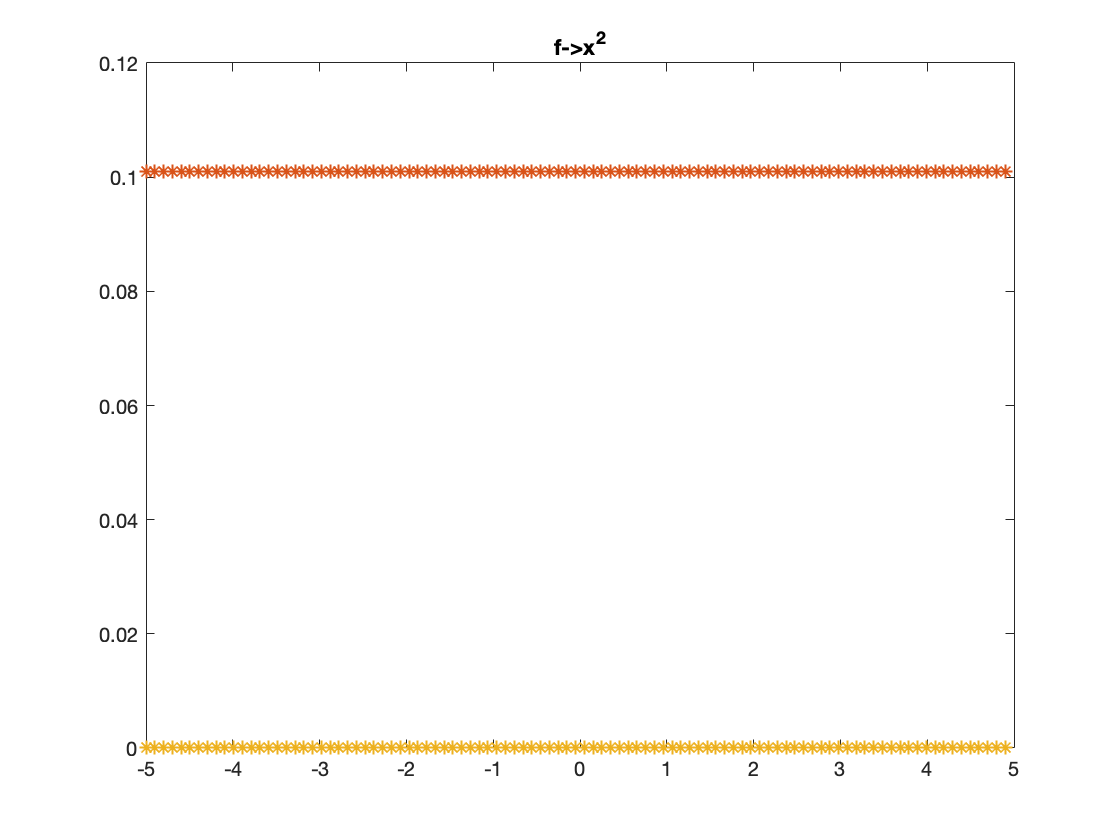

f = @(x) x.^2;
fprime= @(x) 2*x;
errorf=abs(fprime(xf)-forward(f,xf,h));
errorb=abs(fprime(xf)-backward(f,xf,h));
errorc=abs(fprime(xf)-centered(f,xf,h));
plot(xf,errorf,'*-',xf,errorb,'*-',xf,errorc,'*-')
title('f->x^2')

C

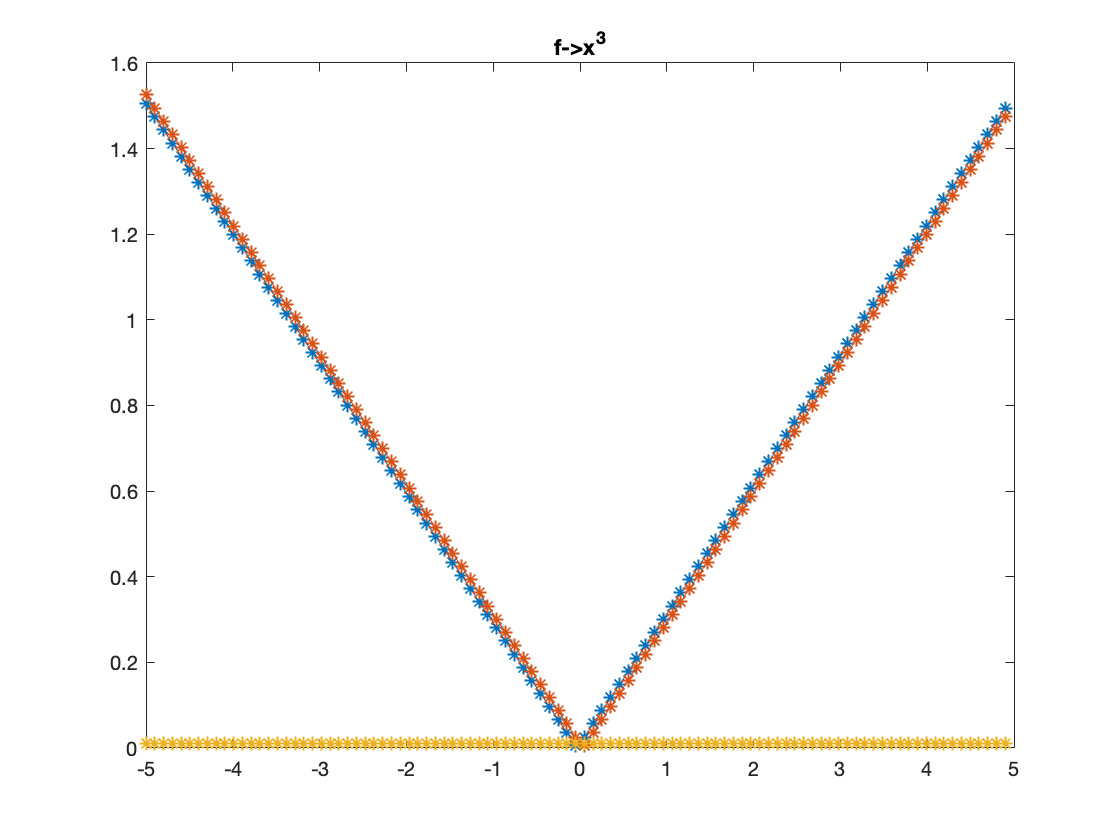

f = @(x) x.^3;
fprime= @(x) 3*x.^2;
errorf=abs(fprime(xf)-forward(f,xf,h));
errorb=abs(fprime(xf)-backward(f,xf,h));
errorc=abs(fprime(xf)-centered(f,xf,h));
plot(xf,errorf,'*-',xf,errorb,'*-',xf,errorc,'*-')
title('f->x^3')

D

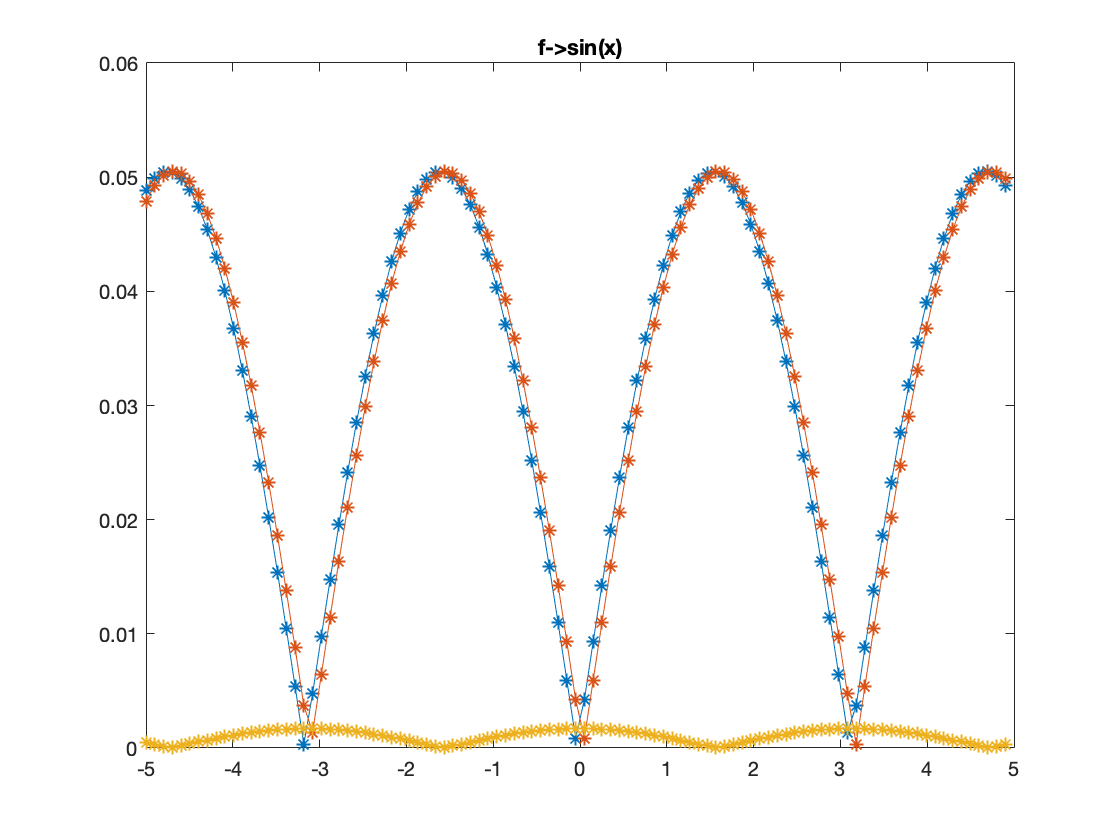

f = @(x) sin(x);
fprime= @(x) cos(x);
errorf=abs(fprime(xf)-forward(f,xf,h));
errorb=abs(fprime(xf)-backward(f,xf,h));
errorc=abs(fprime(xf)-centered(f,xf,h));
plot(xf,errorf,'*-',xf,errorb,'*-',xf,errorc,'*-')
title('f->sin(x)')

2.

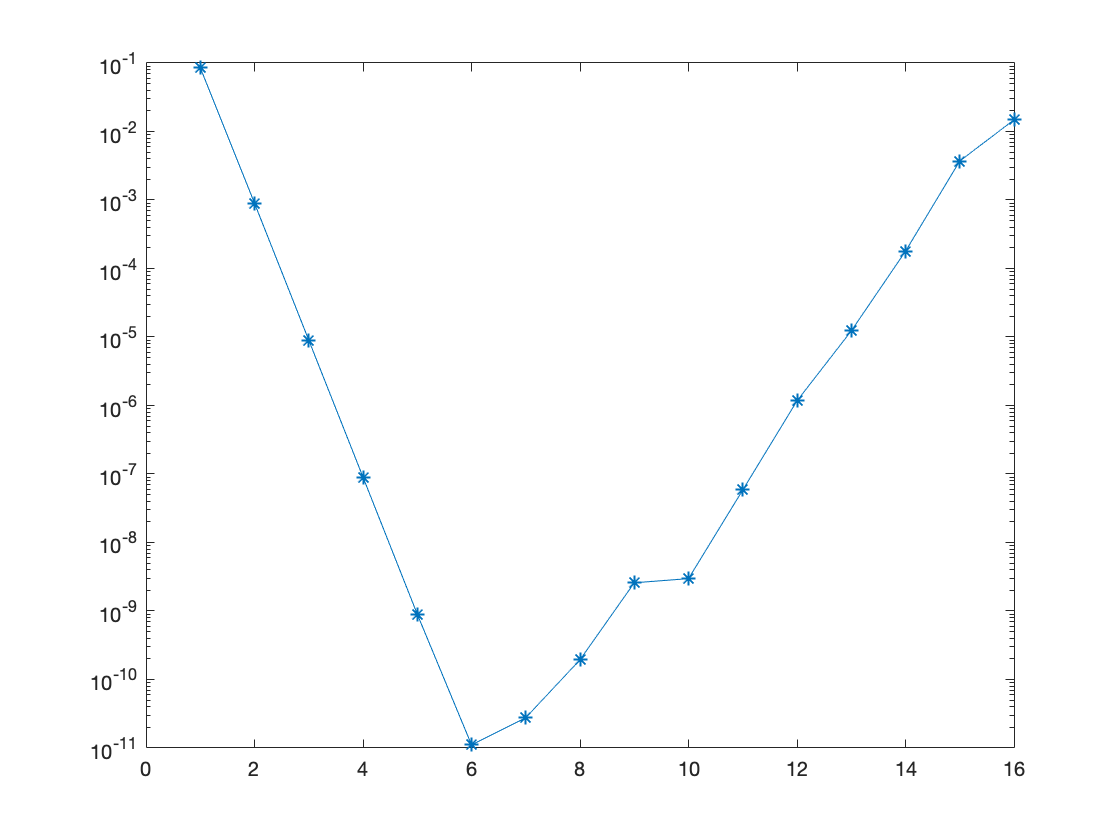

f = @(x) sin(x);
fprime= @(x) cos(x);
for i=0:15
    k(i+1)=1/(10^i);
    error(i+1)=abs(fprime(1)-centered(f,1,k(i+1)));
end
semilogy(error,'*-')

3.

X=[1,2,3];
p = @(p) polyval([2 0 1], p);
Y=p(X);
num_diff(X,Y,3,10)

a =      2     0     1


ans = 0

%if D is bigger than n+1 it evaluates 0

function o = forward(f,x,h)
o= (f(x+h)-f(x))/h;
end
function o = backward(f,x,h)
o= (f(x)-f(x-h))/h;
end
function o = centered(f,x,h)
o= (f(x+h)-f(x-h))/(2*h);
end

function a = linterp_poly(X, Y)
    a = zeros(1,numel(X));
    for i = 1:numel(X)
        aa = poly(X([1:i-1 i+1:end]));
        a = a + Y(i) * aa / polyval(aa, X(i));
    end
end
function y = num_diff(X, Y, x, d)
    a=linterp_poly(X,Y);
    for i=1:d
       a=polyder(a);
    end
    y=polyval(a,x);
end
